# 模拟滤波器到数字滤波器的转换

二阶高通巴特沃斯滤波器

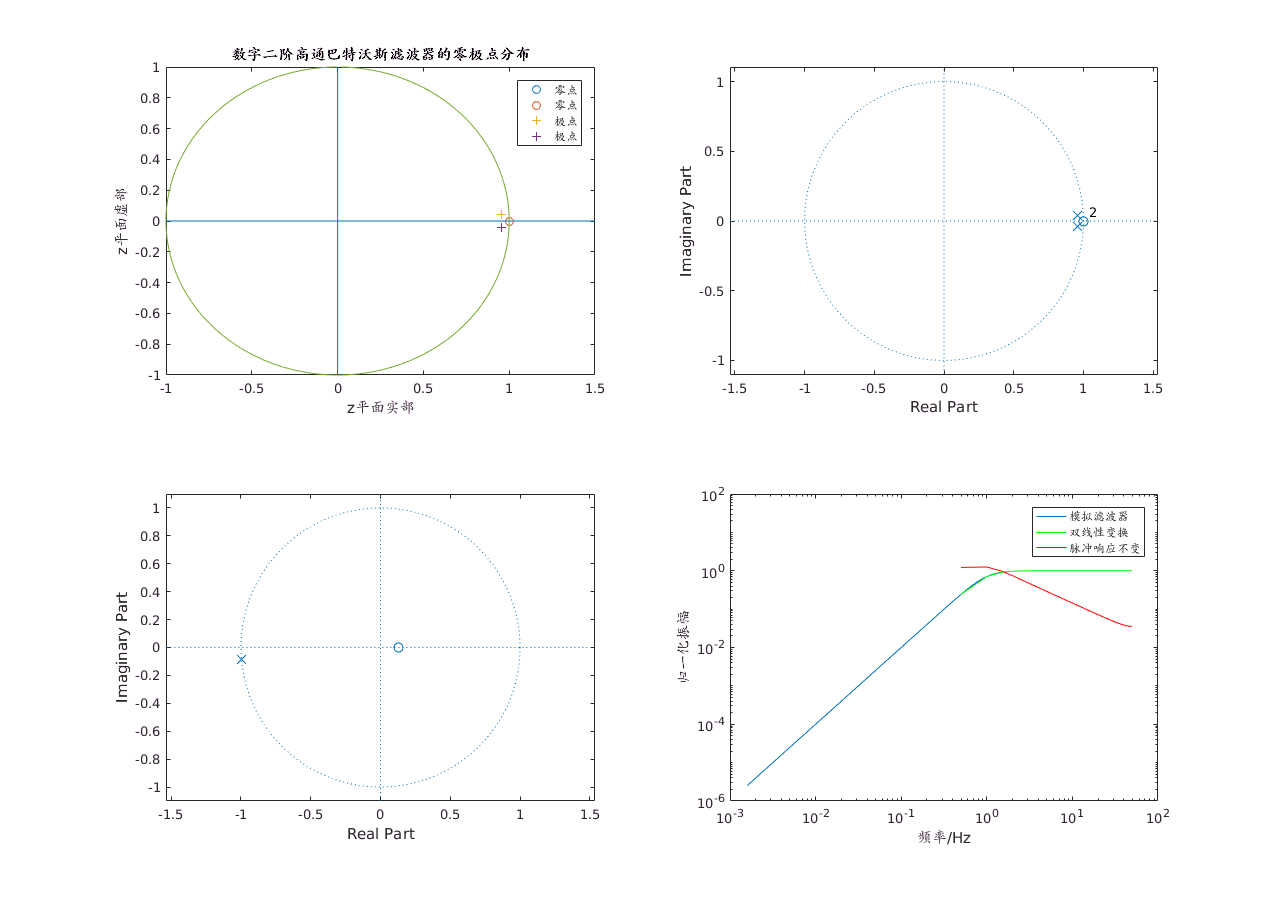

clearvars

Fs           = 100;                   %采样率
gVal         = 1;                     %增益
cutHz        = 1;                     %截止频率
cutFre      = 2*pi*cutHz;
r2          = sqrt(2);
%传递函数有理分式分子（参见式（2.61）
b(1)        = 1;
b(2)        = 0;
b(3)        = 0;
%传递函数分母
a(1)        = 1;
a(2)        = r2*cutFre;
a(3)        = cutFre^2;
%零点和极点
ze(1)       = 0;
ze(2)       = 0;
po(1)       = -r2*cutFre*(1+1i)/2;
po(2)       = -r2*cutFre*(1-1i)/2;
po0         = roots(b);
ze0         = roots(a);
num_ze      = 2;
num_po      = 2;
[mn,nn]     = size(ze);
%双线性变换，使用零极点
[zd,pd,kd]  = bilinear(ze',po',gVal,Fs);
num_zd      = length(zd);
num_pd      = length(pd);

scrsz = get(groot,'ScreenSize');
figure('Position',[scrsz(3)/4 scrsz(4)/2 scrsz(3)/1.5 scrsz(4)/1.2]);
subplot(2,2,1);
for i=1:num_zd
    plot(real(zd(i)),imag(zd(i)),'o');
    hold on
end
for i=1:num_pd
    plot(real(pd(i)),imag(pd(i)),'+');
    hold on
end

x = zeros(1,360);
y = zeros(1,360);
for i=1:360
    x(i)=sin(i*pi/180);
    y(i)=cos(i*pi/180);
end

plot(x,y);
title('数字二阶高通巴特沃斯滤波器的零极点分布')
xlabel('z平面实部')
ylabel('z平面虚部')
legend('零点','零点','极点','极点')
line([-1,1.5],[0,0])
line([0,0],[-1,1])

%双线性变换，使用有理分式的分子b和分母a
[bz,az]         = bilinear(b,a,Fs);
zd0             = roots(bz);
pd0             = roots(az);
[h0,w0]         = freqz(bz,az,Fs);  
%脉冲响应不变法
[bz1,az1]       = impinvar(b,a,Fs);   %注意，脉冲响应不变法不适于高通和带阻滤波器
[h2,w2]         = freqz(bz1,az1,Fs);

%求数字滤波器的零极点
bzlen           = length(bz1);
azlen           = length(az1);
zd1             = roots(bz1);
pd1             = roots(az1);

subplot(2,2,2);
zplane(bz,az);   %双线性
subplot(2,2,3);
zplane(zd1',pd1');

subplot(2,2,4);
[h00,w00]       = freqs(b,a);       %模拟滤波器
loglog(w00/(2*pi),abs(h00));
hold on
loglog(w0*Fs/(2*pi),abs(h0),'g');   %双线性变换
hold on  
loglog(w2*Fs/(2*pi),abs(h2),'r');   %脉冲响应不变
legend('模拟滤波器','双线性变换','脉冲响应不变')
xlabel('频率/Hz')
ylabel('归一化振幅')

## 直接计算双线性变换得到的极点

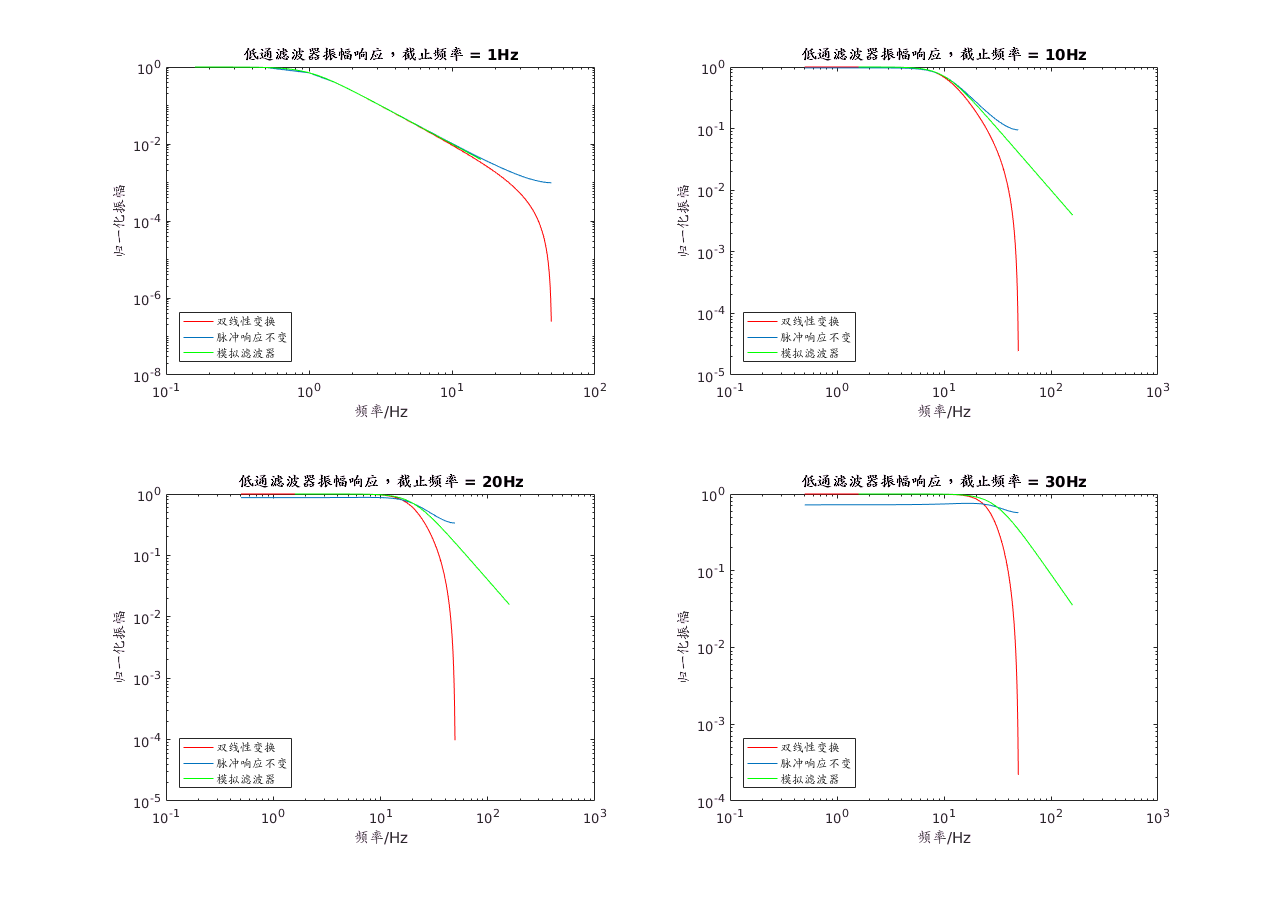

%低通滤波器
% omega0          = 2*pi*cutHz;
%传递函数有理分式分子（参见式（2.61）
%零个零点
%传递函数分母
% p(1)            = -4.4429+4.4429i;
% p(2)            = -4.4429-4.4429i;
% [b,a]           = zp2tf([],p,-omega0^2);
% [h4,w4]         = freqs(b,a);
% figure
% loglog(w4/(2*pi),abs(h4),'r')

scrsz = get(groot,'ScreenSize');
figure('Position',[scrsz(3)/4 scrsz(4)/2 scrsz(3)/1.5 scrsz(4)/1.2]);
cutHzs=[1 10 20 30];
for i=1:4
    ordNum          = 2; 
    cutHz           = cutHzs(i);
    cutFre          = cutHz*2*pi;
    [z,p,gVal]      = butter(ordNum,cutFre,'s');
    [b,a]           = zp2tf(z,p,gVal);
    [h,w]           = freqs(b,a);
    % loglog(w/(2*pi),abs(h))

    % 变成数字滤波器
    [bd_bi,ad_bi]   = bilinear(b,a,Fs);
    [bd_im,ad_im]   = impinvar(b,a,Fs);
    [h_bi,w_bi]     = freqz(bd_bi,ad_bi,Fs);
    [h_im,w_im]     = freqz(bd_im,ad_im,Fs);
    subplot(2,2,i)
    loglog(w_bi*Fs/(2*pi),abs(h_bi),'r');
    hold on
    loglog(w_im*Fs/(2*pi),abs(h_im));
    hold on
    loglog(w/(2*pi),abs(h),'g')
    legend('双线性变换','脉冲响应不变','模拟滤波器','Location','southwest')
    xlabel('频率/Hz')
    ylabel('归一化振幅')
    title(['低通滤波器振幅响应，截止频率 = ' num2str(cutHz) 'Hz'])
end

## 有限差分近似

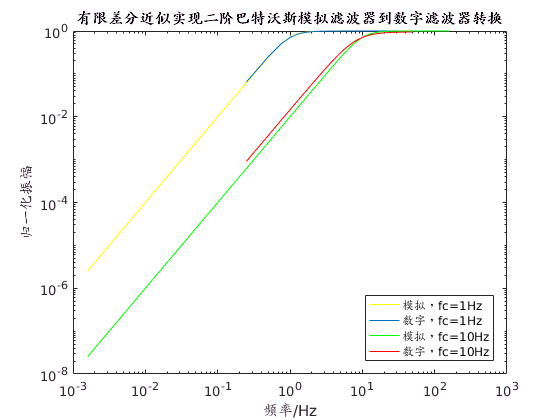

r2              = sqrt(2);
cutHz           = 1;
Fs              = 100;
cutFre          = 2*pi*cutHz;
%模拟传递函数有理分式分子（参见式（2.61）
b(1)            = 1;
b(2)            = 0;
b(3)            = 0;
%传递函数分母
a(1)            = 1;
a(2)            = r2*cutFre;
a(3)            = cutFre^2;
gVal               = Fs^2+r2*cutFre*Fs+cutFre^2;
b1(1)           = 1/gVal;
b1(2)           = -2/gVal;
b1(3)           = 1/gVal;

a1(1)           = 1;
a1(2)           = -(2*(Fs^2)+r2*cutFre*Fs)/gVal;
a1(3)           = Fs^2/gVal;
num             = 200;
[h_de,w_de]     = freqz(b1,a1,num);
%归一化
df              = Fs/(2*num);
n_f             = cutHz/df+1;
norm            = abs(h_de(n_f))/0.707;

figure
[h00,w00]=freqs(b,a);  %模拟滤波器
loglog(w00/(2*pi),abs(h00),'-y');
hold on
loglog(w_de*Fs/(2*pi),abs(h_de)/norm);
hold on

cutHz           = 10;
Fs              = 100;
cutFre          = 2*pi*cutHz;
%传递函数有理分式分子（参见式（2.61）
b(1)            = 1;
b(2)            = 0;
b(3)            = 0;
%传递函数分母
a(1)            = 1;
a(2)            = r2*cutFre;
a(3)            = cutFre^2;
%------------------------------有限差分近似
gVal               = Fs^2+r2*cutFre*Fs+cutFre^2;
b1(1)           = 1/gVal;
b1(2)           = -2/gVal;
b1(3)           = 1/gVal;
r2              = sqrt(2);

a1(1)           = 1;
a1(2)           = -(2*(Fs^2)+r2*cutFre*Fs)/gVal;
a1(3)           = Fs^2/gVal;
aa              = a1;
bb              = b1;
[h_de,w_de]     = freqz(b1,a1,num);
%归一化
f_de            = w_de*Fs/(2*pi);
df              = Fs/(2*num);
n_f             = cutHz/df+1;
f_n             = f_de(n_f);
norm            = abs(h_de(n_f))/0.707;

[h00,w00]       = freqs(b,a);  %模拟滤波器
loglog(w00/(2*pi),abs(h00),'-g');
hold on
loglog(w_de*Fs/(2*pi),abs(h_de)/norm,'r')
xlabel('频率/Hz')
ylabel('归一化振幅')
legend('模拟，fc=1Hz','数字，fc=1Hz','模拟，fc=10Hz','数字，fc=10Hz','Location','southeast')
title('有限差分近似实现二阶巴特沃斯模拟滤波器到数字滤波器转换')